# LQR analysis for cart pole

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.3) %linewidh on plots
set(0,'defaultfigurecolor',[1 1 1])

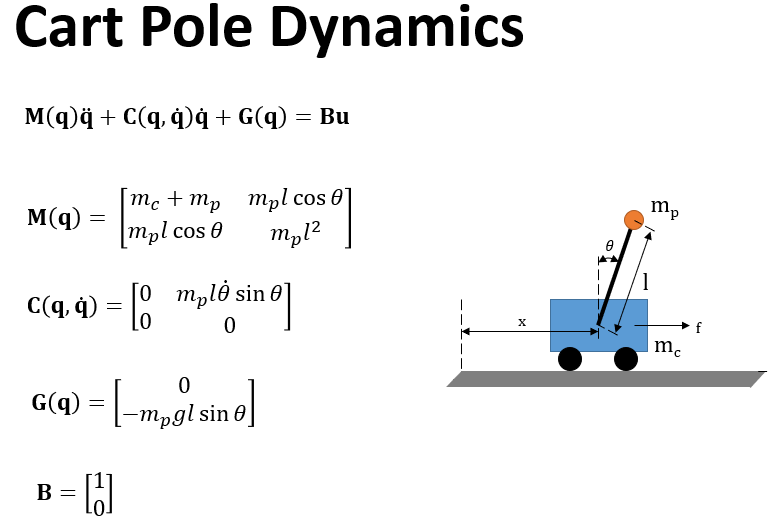

## **Writing this in state space form:**

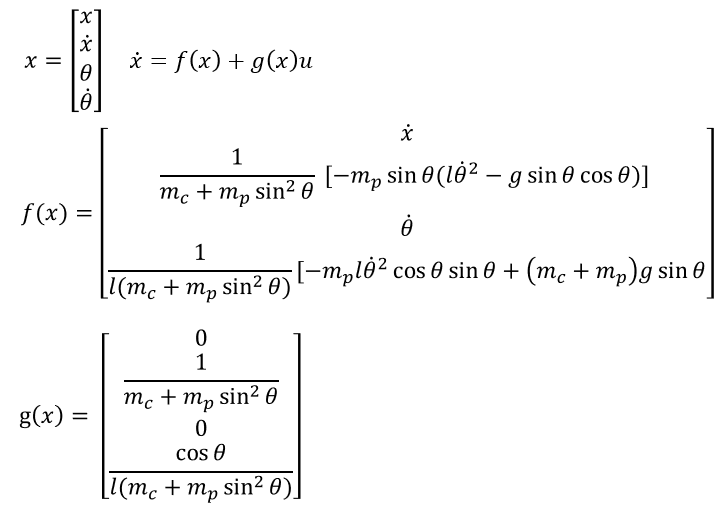

m = 2; M = 8;
l = 0.5; gr = 9.8; 

f = @PendCartModel_F;

## Parameters setup

n=4; % dimension
Dom = [-2*pi 2*pi]; % Domain
nb_IC = 1e4; %initial coditions

## Linearize system

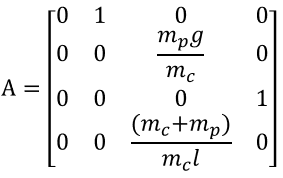    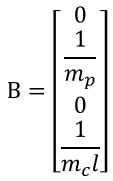

n=4; % dimension
x = sym('x',[n;1]); 
u = sym('u',[1,1]);
x0 = [0;0;0;0];

A = double(subs(jacobian(f(0,x,0),x),x,x0));
B = double(subs(jacobian(f(0,x0,u),u),u,0));

% eps = -0.1;
% A(1,1) = eps;

%A1 = [0 1 0 0; 0 0 m*gr/M 0;0 0 0 1;0 0 (m+M)*gr/(M*l) 0];
%B1 = [0; 1/M; 0; 1/(M*l)];

[V,D1,W1] = eig(A); 

%linear eigenfunctions realization from complex eigenfunctions
[W, D] = cdf2rdf(W1, D1); 

## Uncontrolled response

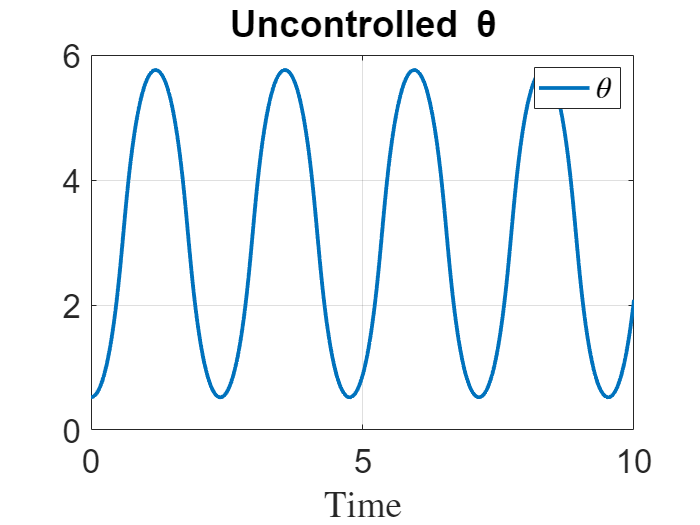

options = odeset('RelTol',1e-6,'AbsTol',1e-30);
tspan = 0:0.01:10;
x0 = [0;0;pi/6;0];
[t, x] = ode45(@(t,x) f(t, x, 0), tspan, x0, options);

figure()
plot(t, x(:,3))
grid on;
title('Uncontrolled \theta')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$\theta$');
set(LEG,'interpreter','latex')

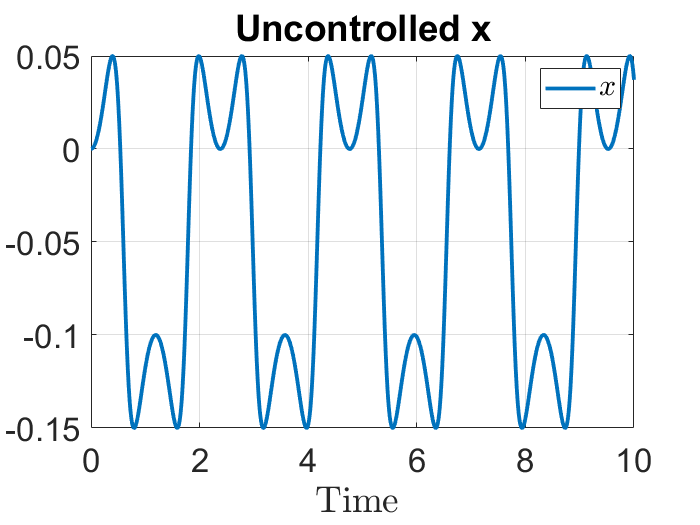

figure()
plot(t, x(:,1))
grid on;
title('Uncontrolled x')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$\theta$');

LEG = legend('$x$');
set(LEG,'interpreter','latex')

## Check for controllability

if(rank(ctrb(A,B))==4)
   disp('System is controllable')
else
   disp('System is unctrollable')
end

System is controllable


## Solve ARE in state space

Q = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %cost on states
P = are(A,B*B',Q)

P = 	1.0e+03 *

    0.0050    0.0119   -0.0439   -0.0100
    0.0119    0.0551   -0.2093   -0.0475
   -0.0439   -0.2093    4.6788    0.9649
   -0.0100   -0.0475    0.9649    0.1995


## LQR Controller

R = 1; %cost on inputs
[K,S,E] = lqr(A,B,Q,R);
uLQR = @(x) -K*(x);

## Simulation

options = odeset('RelTol',1e-6,'AbsTol',1e-30);
tspan = 0:0.01:20;
x0 = [0;0;0.01;0];
[tspan, xLQR] = ode45(@(t,x) f(t, x, uLQR(x)), tspan, x0, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,3)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR succuess


## Plot

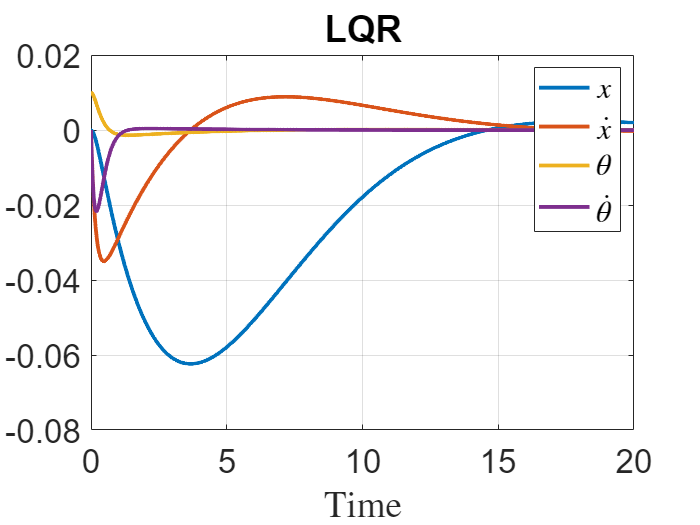

figure()
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend( '$x$', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(LEG,'interpreter','latex')

function Fx = PendCartModel_F(t, x, u)
% states are [x xdot theta thetadot]
mp = 2; mc = 8;
l = 0.5; g = 9.8; 
Sx3 = sin(x(3,:));
Cx3 = cos(x(3,:));

M = mc+mp.*(Sx3.^2);
%% Dynamics wtih control xdot = f(t,x,u)

f1 = (-mp*l.*Sx3.*x(4,:).^2 + u + mp*g.*Cx3.*Sx3) ./ M;
f2 = (-mp*l.*Cx3.*Sx3.*x(4,:).^2 + u.*Cx3 + (mp+mc)*g.*Sx3) ./ (M.*l);

Fx = [x(2,:); f1; x(4,:); f2];
end